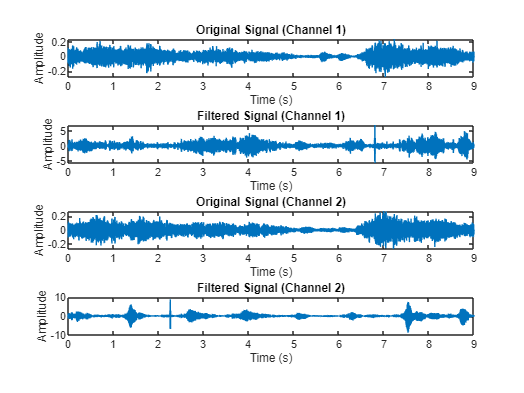

% Load audio file
[data, fs] = audioread('audio.wav');

%Load standard pulse
load('Pulse.mat');

%Compute Fourier transform of the audio signal
data_fft = fft(data);

%Apply zero-padding to the Fourier transform of the pulse
N = length(data);
yp_fft = fft(yp, N);

%Perform complex conjugate multiplication
filtered_signals_fft = data_fft .* conj(yp_fft.');

%Compute inverse Fourier transform
filtered_signals_time = ifft(filtered_signals_fft);

%Normalize filtered signals
filtered_signals_norm = normalize(real(filtered_signals_time));

%Define time vector in seconds
t = (0:length(data)-1) / fs;

%Plot original and filtered signals
figure;
subplot(4, 1, 1);
plot(t, data(:, 1)); %original signal for channel 1
title('Original Signal (Channel 1)');
xlabel('Time (s)')
ylabel('Amplitude')
xlim([0,9]);

subplot(4, 1, 3);
plot(t, data(:, 2)); %original signal for channel 2
title('Original Signal (Channel 2)');
xlabel('Time (s)')
ylabel('Amplitude')
xlim([0,9]);

subplot(4, 1, 2);
plot(t, filtered_signals_norm(:, 1)); %filtered signal for channel 1
title('Filtered Signal (Channel 1)');
xlabel('Time (s)')
ylabel('Amplitude')
xlim([0,9]);

subplot(4, 1, 4);
plot(t, filtered_signals_norm(:, 2)); %filtered signal for channel 2
title('Filtered Signal (Channel 2)');
xlabel('Time (s)')
ylabel('Amplitude')
xlim([0,9]);